**Traitement des données électromyographique sujets sains (FUNCTIONAL)**

Contexte : analyse des données des tâches motrices **fonctionelles** sur 7 muscles de l'épaule lors de différentes actions : 

- FUNCTIONAL1 : porter les mains à la bouche

- FUNCTIONAL2 : toucher le haut de la tête

- FUNCTIONAL3 : porter les mains le plus haut possible au-dessus de la tête

- FUNCTIONAL4 : porter les mains le plus haut possible le long de la colonne vertébrale

Traiment des données complet pour les deux épaules et toutes les tâches

clc; clear all;

Paramètres 

% 1) configureStudyParameters : définition des sujets, muscles 
% et de l'assignation des tâches analytics aux tâches fonctionnelles 

% 2) configureEMGParameters : paramètres du traitement de données tels que le filtre,
% la rms et la normalisation du temps 

% 3) initializeDataArrays : initialisation des matrices pour stocker les
% MVC des tâches analytiques, les signaux normalisées et les SNR

Application du traitement de données 

% 1) calculateMVC : calcul la contraction maximale volontaire pour chaque sujet et muscle
% selon la tâche analytic assignée à chaque muscle en prenant la moyenne des cinq valeurs 
% les plus hautes du signal RMS analytic (normalisation par une tâche sous-maximale standardisée)

% 2) processMuscleSide : traitement des données (4 étapes) avec application
% de la normalisation 

% 3) processFunctionalTask : applique la fonction précédente pour traiter les données 
% pour une tâche fonctionnelle spécifique

Calcul du rapport signal/bruit 

% 1) calculate_snr : calcule le SNR en se basant sur les 10 premiers
% pourcents du signal pour estimer le bruit

% 2) evaluate_snr_quality : donne une évaluation du signal selon la
% puissance du signal par rapport au bruit

Affichage du profil moyen 

% 1) calculateAndDisplayAverageProfile : calcule et affiche les profils moyens

% 2) displayAverageProfile : affiche les profils moyens pour un côté
% spécifique avec les écarts-types

Fonction principale qui permet de visualiser les données traitées de tous les sujets

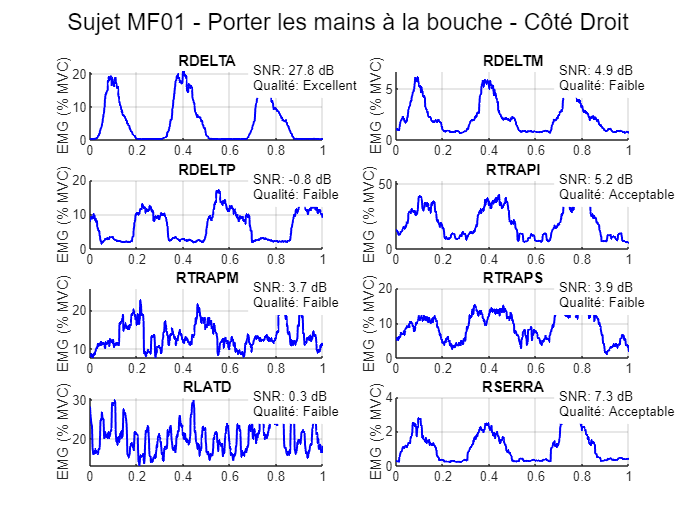

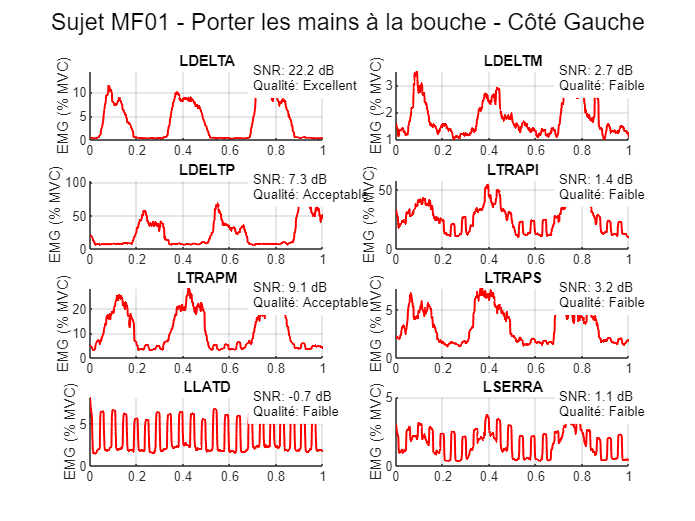

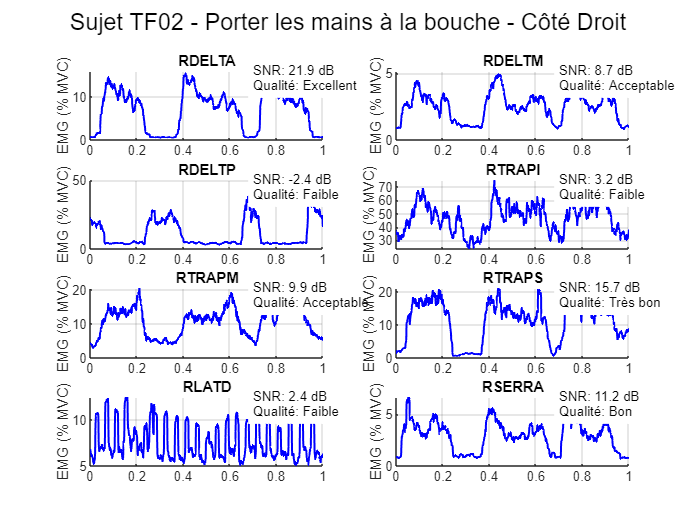

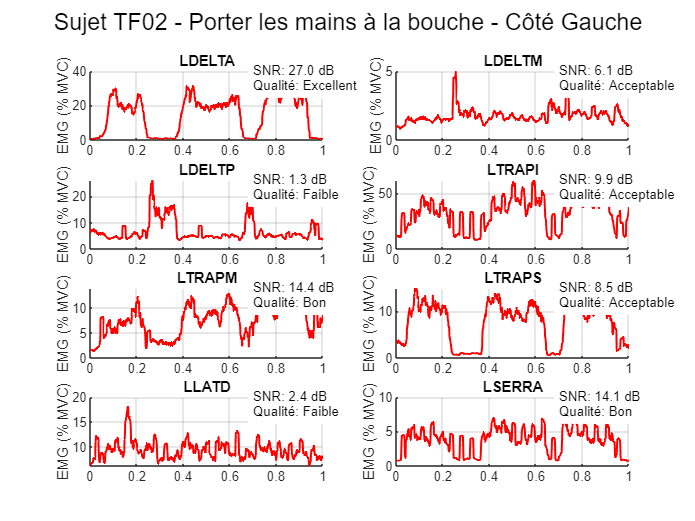

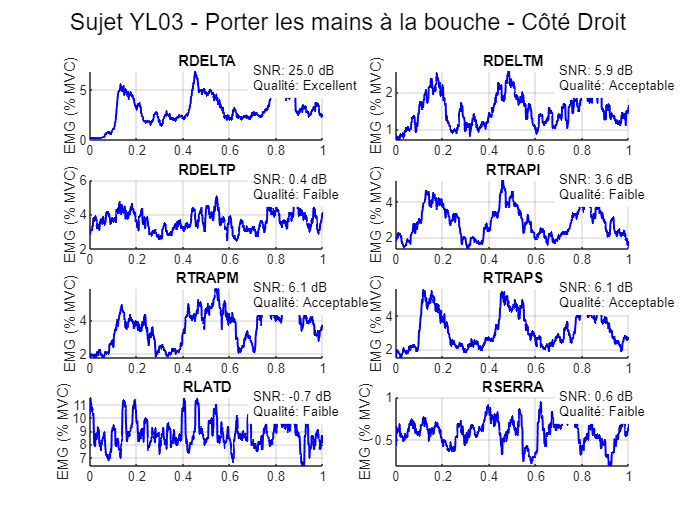

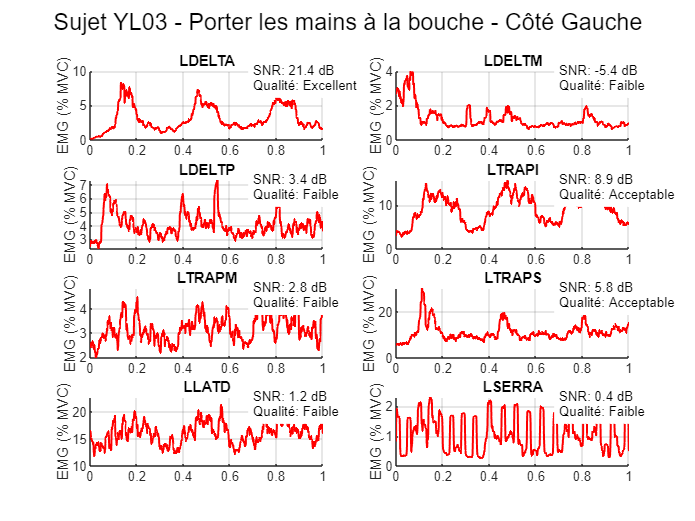

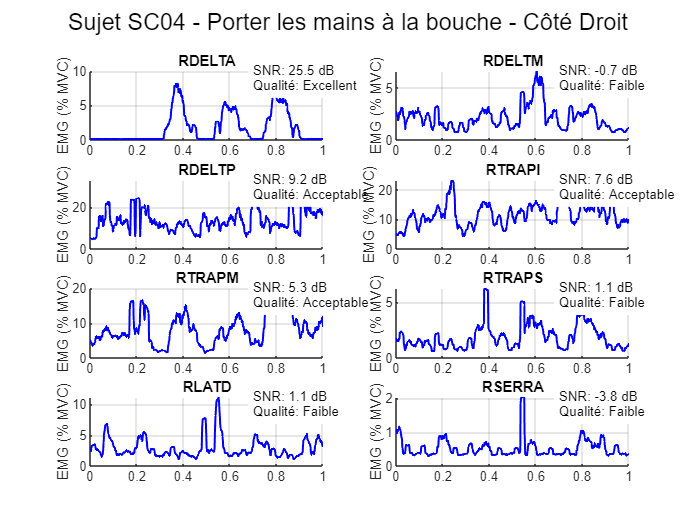

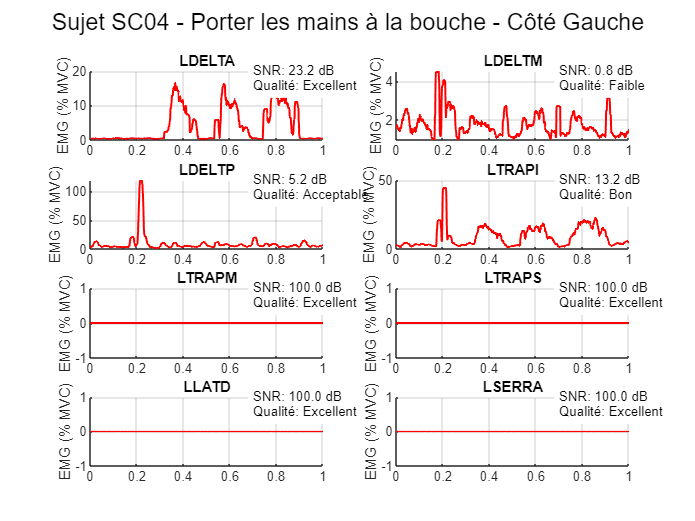

% Aller dans la fonction "main.m" pour séléctionner la tâche voulue 
% dans la variable "selected_functional" (de 1 à 4)
main();

Fonction principale qui permet de visualiser les données traitées de un seul sujet (vérification traitement)

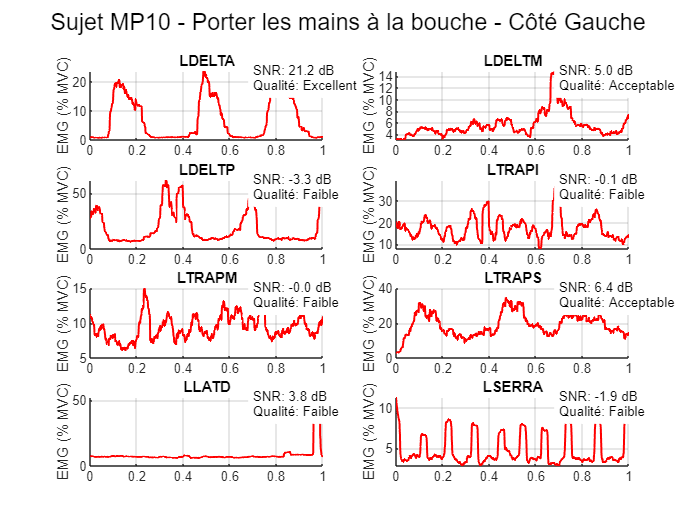

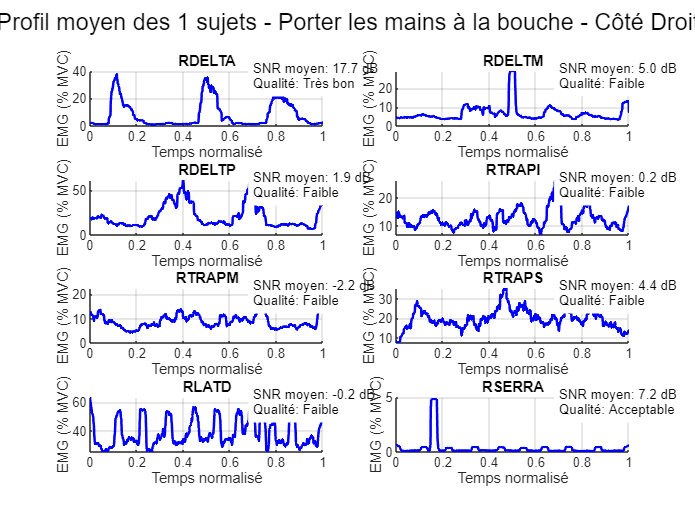

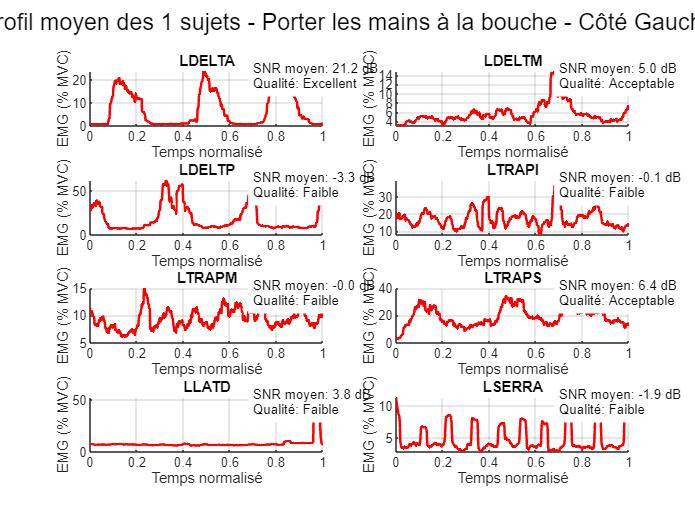

% Va simplifement utiliser "configureStudyParameters_solo" qui définit 
% un seul sujet
main_2();